Read the contents of “cars.csv” into a MATLAB TABLE.

CarsData = readtable('cars.csv');

Display all the variable names in **CarsData** Table.

CarsData.Properties.VariableNames

ans = 1×9 cell array
    {'Car'}    {'MPG'}    {'Cylinders'}    {'Displacement'}    {'Horsepower'}    {'Weight'}    {'Acceleration'}    {'Model'}    {'Origin'}


List all the Car names in an alphabetical order.

sort(CarsData.Car)

ans = 406×1 cell array
    {'AMC Ambassador Brougham'   }
    {'AMC Ambassador DPL'        }
    {'AMC Ambassador SST'        }
    {'AMC Concord'               }
    {'AMC Concord'               }
    {'AMC Concord DL'            }
    {'AMC Concord DL 6'          }
    {'AMC Concord d/l'           }
    {'AMC Gremlin'               }
    {'AMC Gremlin'               }
    {'AMC Gremlin'               }
    {'AMC Gremlin'               }
    {'AMC Hornet'                }
    {'AMC Hornet'                }
    {'AMC Hornet'                }
    {'AMC Hornet'                }
    {'AMC Hornet Sportabout (sw)'}
    {'AMC Matador'               }
    {'AMC Matador'               }
    {'AMC Matador'               }
    {'AMC Matador'               }
    {'AMC Matador'               }
    {'AMC Matador (sw)'          }
    {'AMC Matador (sw)'          }
    {'AMC Pacer'                 }
    {'AMC Pacer d/l'             }
    {'AMC Rebel SST'             }
    {'AMC Rebel SST (sw)'       

Find the Car Name that gives highest MPG (Miles-Per-Gallon)

[maxMPG indx] = max(CarsData.MPG);
CarsData.Car(indx)

ans = 1×1 cell array
    {'Mazda GLC'}


CarsData.MPG(indx)

ans = 46.6000

What is the average MPG of all Cars?

avMPG = mean(CarsData.MPG)

avMPG = 23.0512

List all the Car names that have MPG less than the average MPG of all Cars.

[row col]=find( CarsData.MPG < avMPG);
CarsData.Car(row)

ans = 215×1 cell array
    {'Chevrolet Chevelle Malibu'       }
    {'Buick Skylark 320'               }
    {'Plymouth Satellite'              }
    {'AMC Rebel SST'                   }
    {'Ford Torino'                     }
    {'Ford Galaxie 500'                }
    {'Chevrolet Impala'                }
    {'Plymouth Fury iii'               }
    {'Pontiac Catalina'                }
    {'AMC Ambassador DPL'              }
    {'Citroen DS-21 Pallas'            }
    {'Chevrolet Chevelle Concours (sw)'}
    {'Ford Torino (sw)'                }
    {'Plymouth Satellite (sw)'         }
    {'AMC Rebel SST (sw)'              }
    {'Dodge Challenger SE'             }
    {'Plymouth 'Cuda 340'              }
    {'Ford Mustang Boss 302'           }
    {'Chevrolet Monte Carlo'           }
    {'Buick Estate Wagon (sw)'         }
    {'Plymouth Duster'                 }
    {'AMC Hornet'                      }
    {'Ford Maverick'                   }
    {'AMC Gremlin'                

List all the Cars with model number greater than 80 and manufactured by Japan

[row col]=find( CarsData.Model > 80 & CarsData.Origin == "Japan");
CarsData.Car(row)

ans = 21×1 cell array
    {'Toyota Starlet'    }
    {'Honda Civic 1300'  }
    {'Subaru'            }
    {'Datsun 210 MPG'    }
    {'Toyota Tercel'     }
    {'Mazda GLC 4'       }
    {'Honda Prelude'     }
    {'Toyota Corolla'    }
    {'Datsun 200SX'      }
    {'Mazda 626'         }
    {'Toyota Cressida'   }
    {'Datsun 810 Maxima' }
    {'Mazda GLC Custom l'}
    {'Mazda GLC Custom'  }
    {'Nissan Stanza XE'  }
    {'Honda Accord'      }
    {'Toyota Corolla'    }
    {'Honda Civic'       }
    {'Honda Civic (auto)'}
    {'Datsun 310 GX'     }
    {'Toyota Celica GT'  }


List all the countries of origin who have manufactured cars with 6 cylinders.

[row col]=find( CarsData.Cylinders == 6);
C = CarsData.Origin(row)

C = 84×1 cell array
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'Japan'}
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }
    {'US'   }


C = unique(C) % returns only unique values

C = 3×1 cell array
    {'Europe'}
    {'Japan' }
    {'US'    }


Count the number of cars manufactured by each country between the years 72 and 76 with both years included.

[row col]=find( CarsData.Model >= 72 & CarsData.Model <= 76)

row =     65
    66
    67
    68
    69
    70
    71
    72
    73
    74


col =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


[GC,GR] = groupcounts(CarsData.Origin(row)) 

GC =     32
    23
   104


GR = 3×1 cell array
    {'Europe'}
    {'Japan' }
    {'US'    }


Plot a bar chart showing the number of cars manufactured by different countries.

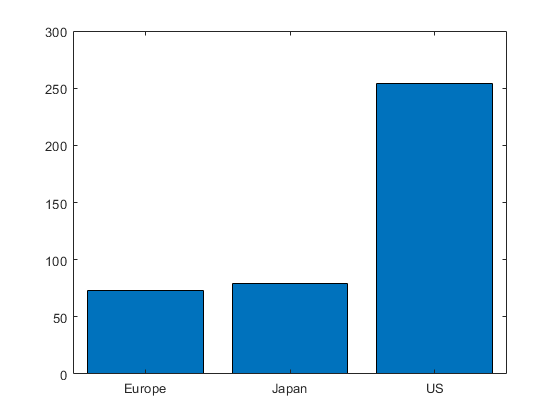

[GC] = groupcounts(CarsData,"Origin");

bar(categorical(GC.Origin),GC.GroupCount) % see help for categorical

Find all cars manufactured by US in the year 1978 and **write** the all information related to them into a CSV file titled “**US_cars.csv**”.

[row col]=find( CarsData.Model == 78 & CarsData.Origin == "US");
T=CarsData(row,[1:end]);
writetable(T,"US_cars.csv");

Given the following rain data for a given Week (Monday to Sunday): Plot these values

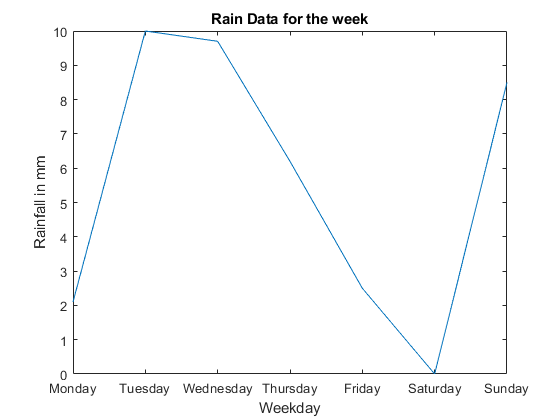

days = {'Monday','Tuesday','Wednesday','Thursday','Friday','Saturday','Sunday'};
rain_data = [2.1 10 9.7 6.2 2.5 0 8.5];
plot(rain_data);
set(gca,'xticklabel',days.');
title('Rain Data for the week');
xlabel('Weekday');
ylabel('Rainfall in mm');

Plotting of dynamic system

%Define Variabes 
T=5; 
a=-1/T; %Start Condition, etc 
x0=1;

t=[0:1:25] %Define the function 

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


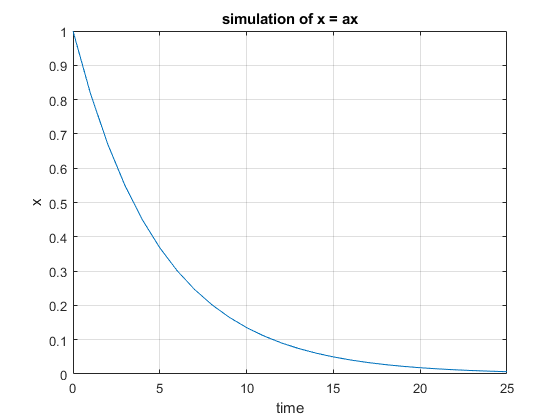

x=exp(a*t)*x0; 
%Plotting 
plot(t,x); 
grid 
title('simulation of x = ax');
xlabel('time'); 
ylabel('x');

Create a stairstep plot of sine evaluated at 40 equally spaced values between 0 and 4*π.*

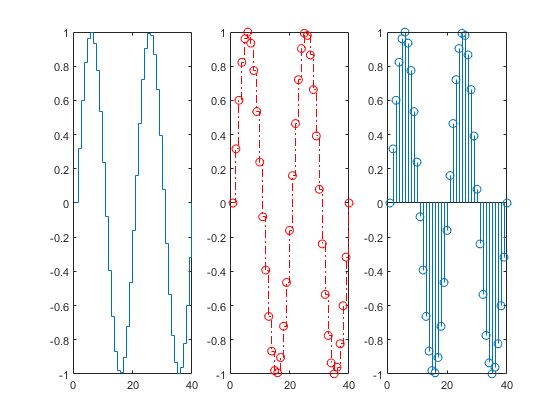

subplot(1,3,1);
X = linspace(0,4*pi,40); 
Y = sin(X); 
stairs(Y); 
subplot(1,3,2);%Plot the same stairstep plot setting the line style to a dot-dashed line, the marker symbol to circles, and the color to red.
stairs(Y, '-.or'); 
subplot(1,3,3);
stem(Y);%Also plot a stem graph of the same data.

Plot magnitude versus frequency on log-log scale for the transfer function  G(s)= 1/(1+0.02s) , where s=jw=j2πf  and f is the frequency

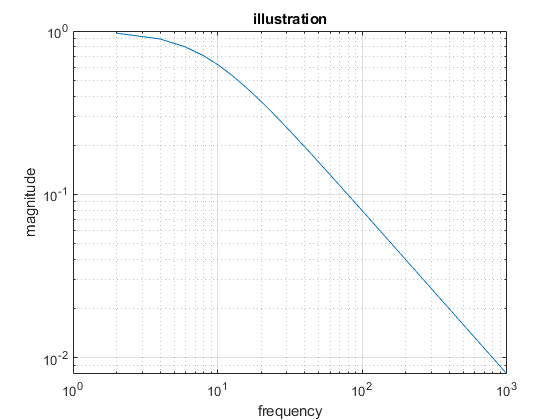

figure;
frequency = 0: 2:1000;
g= 1./(1+j*2*pi*frequency*0.02);
mag=abs(g);
loglog(frequency,mag)
grid on
xlabel('frequency')
ylabel('magnitude')
title('illustration')

Illustrate the use of pie function to show the concentration of different industries in the region as per the following data. Include legends. 

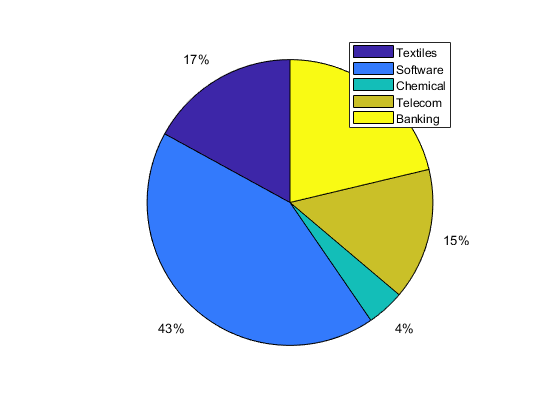

labels = {'Textiles','Software','Chemical','Telecom','Banking'};
data = [8 20 2 7 10];
pie(data);
legend(labels);

Plot function x= e-a, y = a2 where  0<= a <=10, using semilogx function (Use  semilogx(x,y) )

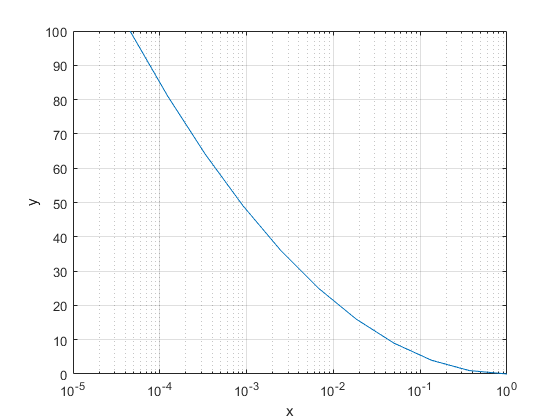

a=0:1:10;
y=a.*a;
x=exp(-a);
semilogx(x,y)
grid on;
xlabel('x');
ylabel('y');

Plot power versus time for 0<t<8 sec, with power on the log scale and time in the linear scale for a motor whose performance equations 

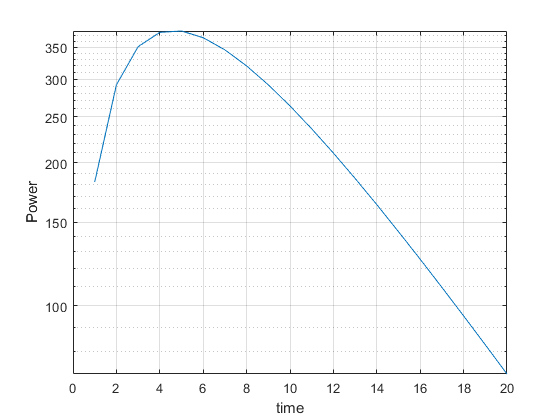

t=0:1:20;
speed_w=190*(1-exp(-0.15*t));
torque_T= 8*exp(-0.15*t);
Power = speed_w.*torque_T;
semilogy(t,Power);
grid on;
ylabel('Power');
xlabel('time');